# ASK_main

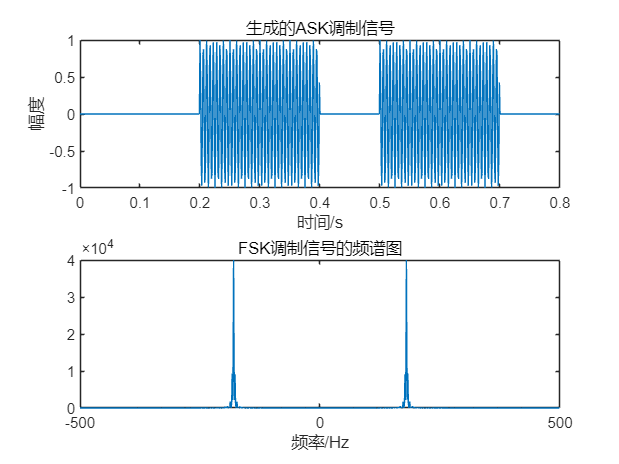

clc;
clear;

% 确定参数
Fs = 1000;  % 采样频率
fc = 180;   % 载波频率
fb = 10;    % 基带信号频率
sps = Fs / fb;
data_length = 8;
% data = [1 0 1 1 0 1 1 0]; % 输入数据序列
data = randi([0, 1], 1, data_length);
N = length(data); % 数据序列长度

% 生成ASK信号
[t,ASK] = ASK_modulation(Fs,fc,data,sps);
[freq, spectrum] = analyze_spectrum(ASK, Fs, 1000); % 分析频谱
figure(1);
subplot(2,1,1);
plot(t,ASK);
title('生成的ASK调制信号');
xlabel('时间/s');% x轴标签
ylabel('幅度');  % y轴标签
subplot(2,1,2);
plot(freq, spectrum); % 绘制频谱图像
xlabel('频率/Hz');           % x轴标签
title('FSK调制信号的频谱图');

## 信道模拟

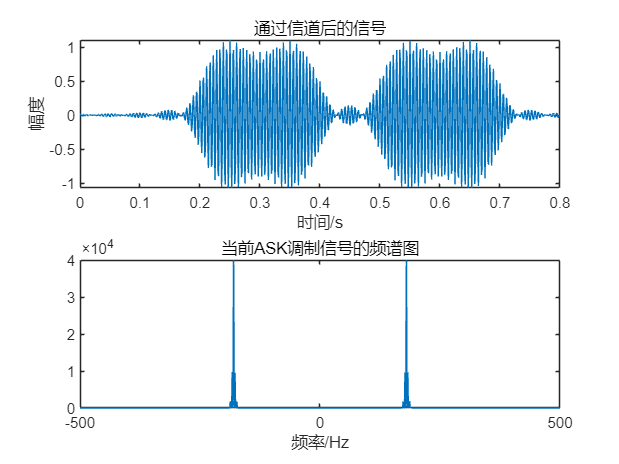

f = 100;
ask = ASK_channel_simulation(ASK,50,fb,fc);

[freq, spectrum] = analyze_spectrum(ask, Fs, 10000); % 分析频谱
figure(2);                    % 绘制第2幅图
subplot(2,1,1);               % 窗口分割成2*1的，当前是第1个子图 
plot(t,ask);                  % 绘制2ASK信号
title('通过信道后的信号');     % 标题
xlabel('时间/s');             % x轴标签
ylabel('幅度');               % y轴标签
subplot(2,1,2);
plot(freq, spectrum);         % 绘制频谱图像
xlabel('频率/Hz');            % x轴标签
title('当前ASK调制信号的频谱图');

## 解调部分

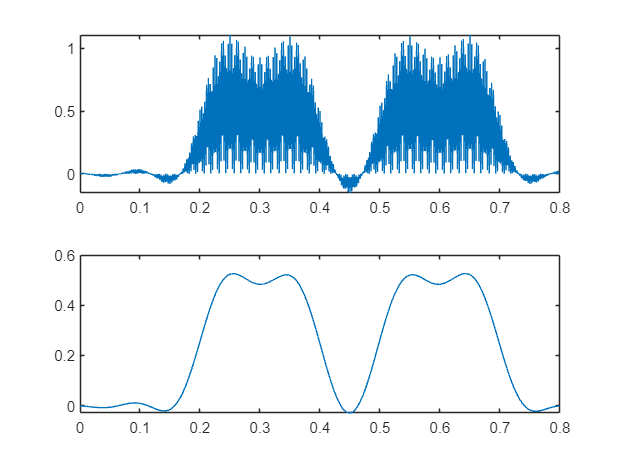

band = 2*fb;% 带宽

[y_t,z_t,ask_out] = ASK_demodulation_c(ask,fc,fb,band,Fs,t);
[freq, spectrum] = analyze_spectrum(ask_out, Fs, 10000);
figure(3);
subplot(2,1,1);
plot(t,ask_out);
title('解调后的FSK波形');
xlabel('时间/s');
ylabel('幅度');
subplot(2,1,2);
plot(freq, spectrum); % 绘制频谱图像
title('解调后的FSK波形的频谱')
xlabel('频率/Hz');

figure(4)
subplot(2,1,1);
plot(t,y_t);
subplot(2,1,2);
plot(t,ask_out);

## 判决结果

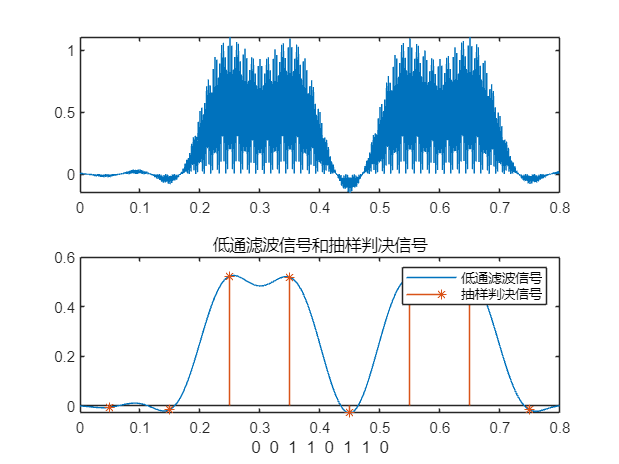

index = (1:N) * sps - sps/2; % 计算索引位置
% stem(t(index), fsk_out(index), '*'); % 在索引位置上绘制特殊标记
th_2 = max(abs(ask_out)) / 2; % 计算阈值
rd_2 = ask_out(index); % 从滤波后的信号中提取对应索引位置上的值
rdata = (sign(rd_2 - th_2) + 1) / 2; % 对提取的值进行判决，得到恢复的数据序列

figure(5);
plot(t, ask_out); % 绘制滤波后的信号图像
hold on;
stem(t(index), rd_2, '*'); % 在索引位置上绘制特殊标记
title("低通滤波信号和抽样判决信号");xlabel(num2str(rdata))
legend("低通滤波信号","抽样判决信号");